%%PRATICA 2

fx = @(t)cos(6*pi/17*t); %Sempre tempo continuo.
%Ver simetria:
%Definir um intervalo de tempo:

t = linspace(-50,50,1000);

%Componente impar e par
xe = (fx(t)+fx(-t))/2;
xo = (fx(t)-fx(-t))/2; 

%Valores da funcao negativa e positiva:
fx_pos_vals = fx_pos(t);
fx_neg_vals = fx_neg(t);


%É par ou impar?

if isequal(fx_pos_vals, fx_neg_vals)
    disp('Par');
elseif isequal(fx_pos_vals, -fx_neg_vals)
    disp('Ímpar');
else 
    disp('Nem par, nem impar');
end

Par


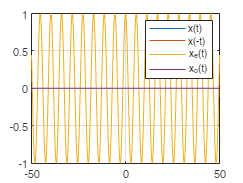

plot(t,fx(t),t,fx(-t),t,xe,t,xo),grid on
legend({'x(t)','x(-t)','x_e(t)','x_o(t)'})


%%ISTO DA MAL??


% PERGUNTAR SOBRE O CS E CA (Simetria conjugada complexa e antisimestria
% complexga conjugadas.

%Periodico vs não-periodico

% Definição da função
fx = @(t) cos(6*pi/17*t);

% Definir um intervalo de tempo
t = linspace(-10, 10, 1000);

% Calcular os valores da função no intervalo de tempo
f_values = fx(t);

% Calcular as diferenças entre os valores da função
dif = diff(f_values); % calcula a diferença entre cada par de valores consecutivos no vetor

% Verificar se as diferenças são todas iguais
if isequal(f_values, fx(-t)) % Comparar os valores da função com os valores da função espelhada
    disp('A função é periódica.');
    periodo =2*pi/(6*pi/17) ; % O período é o dobro do máximo valor de t, assumindo que o intervalo é simétrico
    disp(['O período é ', num2str(periodo)]);
else
    disp('A função não é periódica.');
end

A função é periódica.


O período é 5.6667


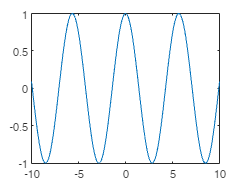

%Deterministico ou estocastico

plot(t, fx(t)); sigma = 0.5;

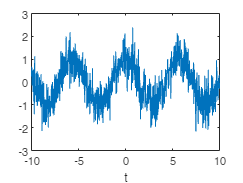

w = sigma*randn(size(t)); %adicionar ruido para ver caso fosse estocastico
plot(t, fx(t)+w); xlabel('t')


%pelo plot podemos ver que é deterministico


%Calcular a energia:
energia = integral(@(x) fx(x).^2, -10, 10);
disp(['A energia do sinal de -10 a 10 é ', num2str(energia)]);

A energia do sinal de -10 a 10 é 9.9171


%É suposto só calcular a energia neste intervalo ou calculamos para
%infinito? No enunciado diz energia finita daí a pergunta.




%Calcular a potencia
% Definição da função
fx = @(x) cos(6*pi/17*x);

% Período do sinal
T = 2*pi/(6*pi/17) % O período é 2pi/(frequência angular)

T = 5.6667

disp(['O período calculado usando a frequência angular é ', num2str(T)]);

O período calculado usando a frequência angular é 5.6667


% Calcular a potência média sobre um período
potencia_media = 1/T * integral(@(x) fx(x).^2, 0, T);

disp(['A potência média do sinal num período é ', num2str(potencia_media)]);

A potência média do sinal num período é 0.5


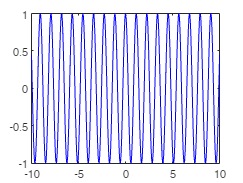

%desenhar a componente impar e par
plot(t, xe, 'b')

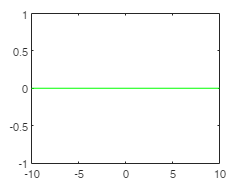


plot(t, xo, 'g')


%Estranhas estas componentes serem tao diferentes
%Perguntar se isto está bem.
